
rng('default');

nSignals = 100;
nSamples = 512;
dt = 0.5;
sigma = 1;

fs = 1/dt;
t = (0:nSamples-1)*dt;

% Choose scales/frequencies for CWT. Use analytic Morlet via cwt with
% sampling frequency to get frequencies directly.
% Precompute frequencies from a single cwt call to determine length.
[~,freqs] = cwt(randn(1,nSamples),'amor',fs);
nFreq = numel(freqs);


% Accumulator for power averaged over time, then over signals
acc_power = zeros(nFreq,1);

for k = 1:nSignals
    x = sigma*randn(1,nSamples);
    wt = cwt(x,'amor',fs); % complex coeffs: size nFreq x nSamples
    power = abs(wt).^2;    % instantaneous power
    time_avg_power = mean(power,2); % average over time (columns)
    acc_power = acc_power + time_avg_power;
end

avg_power_vs_freq = acc_power / nSignals;

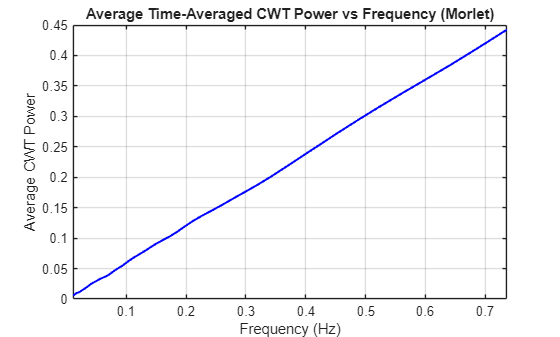


figure;
plot(freqs, avg_power_vs_freq, '-b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)');
ylabel('Average CWT Power');
title('Average Time-Averaged CWT Power vs Frequency (Morlet)');
grid on;
xlim([min(freqs) max(freqs)]);